N = 40;
n = N^2;
rng(0);
A = gallery('poisson',N);
b = randn(n,1);
x0 = zeros(n,1);
eps = 1e-14;
maxiter = 3000;

lmin = 4 - 4 * cos(pi * 1/(1+N));
lmax = 4 + 4 * cos(pi * 1/(1+N));

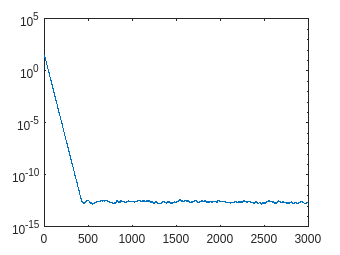

[x,resvec] = tschebyscheff(x0, A, b, lmin, lmax, maxiter, eps);
%(x0, A, b, f1, f2, maxiter, tol)
figure
semilogy(resvec)
hold on

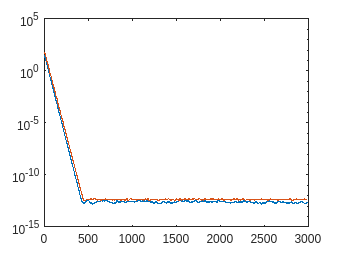

[x,resvec] = tschebyscheff2(x0, A, b, lmin, lmax, maxiter, eps);
semilogy(resvec)

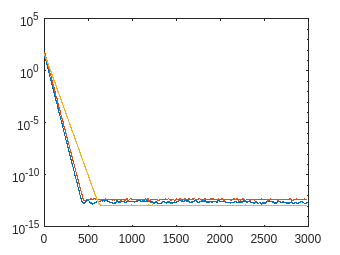

[x,resvec] = tschebyscheff2(x0, A, b, lmin, 2* lmax, maxiter, eps);
semilogy(resvec)

%[x,resvec] = tschebyscheff2(x0, A, b, lmin, lmax-lmin, maxiter, eps);
%semilogy(resvec)

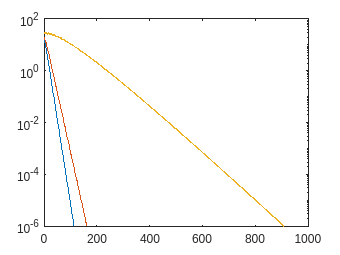

[x,resvec] = tschebyscheff2(x0, A, b, 10 * (1/(1+N)^2) * lmin, lmax, maxiter, eps);
semilogy(resvec)

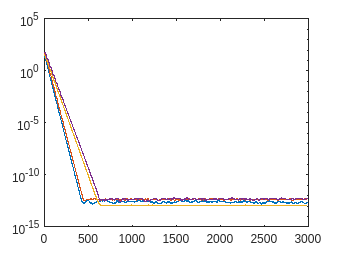

[x,resvec] = tschebyscheff2(x0, A, b, 0.5 * lmin, lmax, maxiter, eps);
semilogy(resvec)

gamma = (lmax - lmin)/ (lmax + lmin);
alpha = 2 / (1 + sqrt (1 - gamma * gamma))

alpha = 1.8578

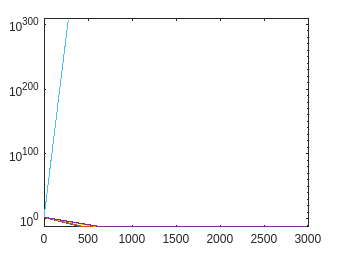

[x,resvec] = richardson2ndorder(x0, A, b, alpha, maxiter, eps);
semilogy(resvec)

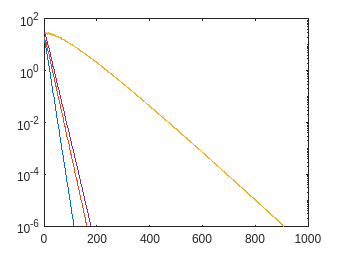

hold off